clear;
close all;

% Compute a feature vector for a time series
XTrain = load('H:\rest_tremor\segment\Fifteenseg\fifteenseg_imu.mat').ecg_signals;

for i = 1:10
    
    y = XTrain{1,1}(i,:);
    featVector = TS_CalculateFeatureVector(y,true); % compute the default feature vector for x
    feat{1,1}(i,:) = featVector;
    
    featVector = 0;
    y = 0;
    
    fprintf(strcat('Dimension',num2str(i),' has been computed.\n')); % 提示完成计算的维度
end

Importing default set of time-series features
Returning a table with metadata for 7702 operations.
Returning a table with metadata for 1064 master operations.
Matlab parallel processing pool already open with 6 workers
Computation will be performed across multiple cores using Matlab's Parallel Computing Toolbox.
***** The time series Input Timeseries is a row vector. Not sure how it snuck through the processing cracks, but I need a column vector...
I'll transpose it for you for now....
=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=
Preparing to calculate Input Timeseries
ts_id = 1, N = 375 samples
Computing 7702 operations.
=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=

Evaluating 1064 master operations...
[ts_id = 1, mop_id = 9 (9/1064)] DN_Mean(x,'midhinge')... evaluated (< 1ms).
[ts_id = 1, mop_id = 8 (8/1064)] DN_Mean(x,'median')... evaluated (< 1ms).
[ts_id = 1, mop_id = 7 (7/1064)] DN_Mean(x,'rms')... evaluated (< 1ms).
[ts_id = 1, m

Using input file: INP_test_ts.mat
We have 3 time series (rows) in your data matrix, timeSeriesData (loaded from INP_test_ts.mat).


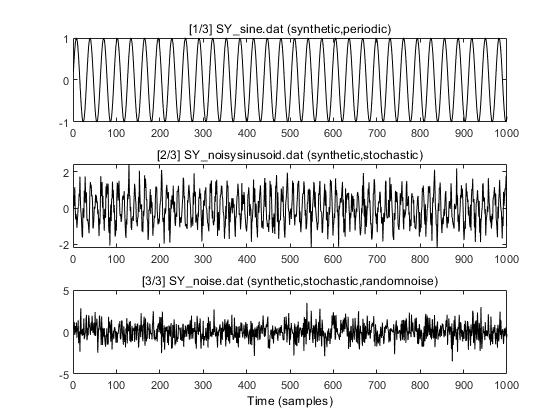

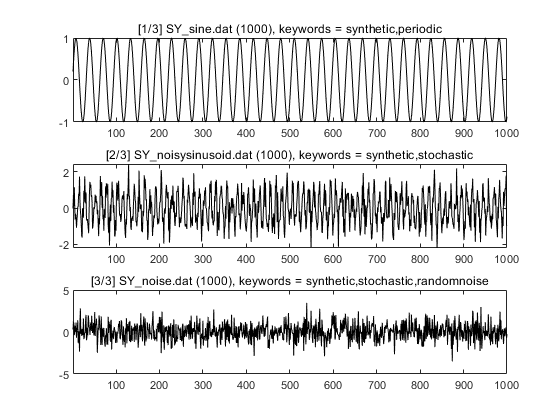


[1/3] SY_sine.dat (1000), keywords = synthetic,periodic --- loaded successfully.


[2/3] SY_noisysinusoid.dat (1000), keywords = synthetic,stochastic --- loaded successfully.
[3/3] SY_noise.dat (1000), keywords = synthetic,stochastic,randomnoise --- loaded successfully.
All time-series data loaded; 3/3 passed quality tests.
Returning a table with metadata for 3 time series.
Returning a table with metadata for 1064 master operations.
Returning a table with metadata for 7702 operations.
Successfully initialized HCTSA.mat with 3 time series, 1064 master operations, and 7702 operations


TS_Init('INP_test_ts.mat');

x = feat{1,1};
x(isnan(x)==1) = 0;
x(x==inf) = 0;
[coeff,score,latent,tsquared,explained] = pca(x');

% Compute all missing values in HCTSA.mat using parallel processing:
TS_Compute(true);

Loading data from HCTSA.mat... Done.
Calculation has begun on 30-Dec-2020 21:45:55 using 3 datasets and 7702 operations


=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=
; ; ; : : : : ; ; ;    30-Dec-2020 21:45:55     ; ; ; : : : ; ; ;
- - - - - - - - - - - Time series 1 / 3 - - - - - - - - - - -
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).
Matlab parallel processing pool opened with 6 workers
Computation will be performed across multiple cores using Matlab's Parallel Computing Toolbox.
=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=
Preparing to calculate SY_sine.dat
ts_id = 1, N = 1000 samples
Computing 7702 operations.
=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=-=

Evaluating 1064 master operations...
[ts_id = 1, mop_id = 36 (36/1064)] DN_Moments(x,8)... evaluated (84ms).
[ts_id = 1, mop_id = 35 (35/1064)] DN_Moments(x,7)... evaluated (1ms).
[t

TS_LabelGroups;

Retrieving data from HCTSA.mat by default.
Loading data from HCTSA.mat... Done.
No keywords assigned for labeling. Attempting to use unique keywords from data...
Shall I use the following 4 keywords: 'periodic', 'randomnoise', 'stochastic', 'synthetic'?
Group labeling complete in < 1ms.


错误使用 TS_LabelGroups (line 159)
3 time series have multiple group assignments: SY_sine.dat, SY_noisysinusoid.dat, SY_noise.dat.

Loading data from HCTSA.mat... Done.


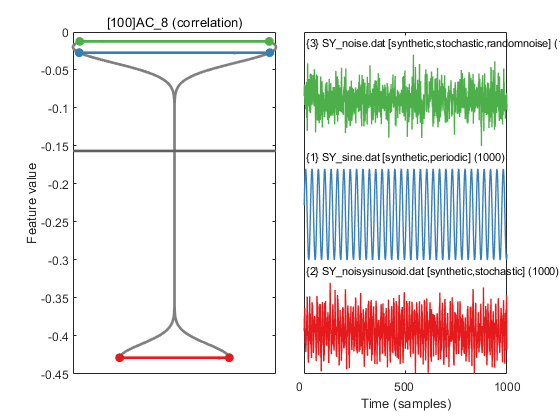

Plotting the 3 time series matching indices provided
Plotting 3 (/3) time series from 1 classes


TS_FeatureSummary(100)

Loading data from HCTSA.mat... Done.


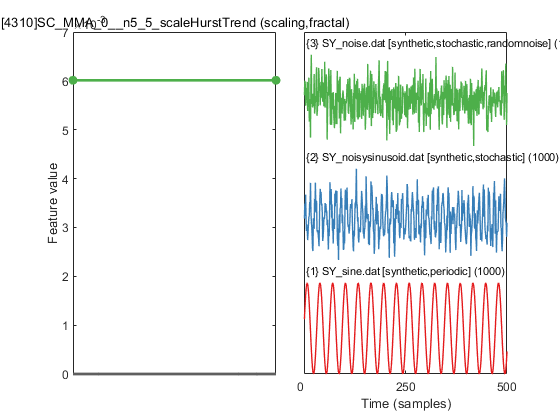

Plotting the 3 time series matching indices provided
Plotting 3 (/3) time series from 1 classes


annotateParams = struct('maxL',500);
TS_FeatureSummary(4310,'raw',true,annotateParams);

Plotting 3 (/3) time series from 1 classes


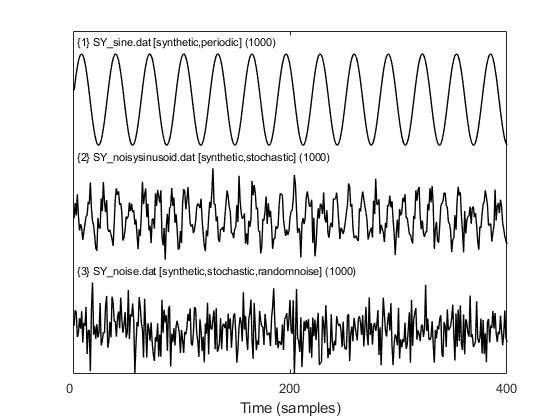

whatData = 'norm'; % Get data from HCTSA_N.mat
plotWhatTimeSeries = 'all'; % plot examples from all time series
plotHowMany = 10; % how many to plot
maxLength = 400; % maximum number of samples to plot for each time series
TS_PlotTimeSeries(whatData,plotHowMany,plotWhatTimeSeries,maxLength);

TS_Normalize;

Using the mixed sigmoidal transform: 'mixedSigmoid'
Removing time series with more than 30.00% special-valued outputs
Removing operations with more than 0.00% special-valued outputs
Loading data from HCTSA.mat... Done.

There are 1297 special values in the data matrix.
(pre-filtering): Time series vary from 94.33--94.46% good values
(pre-filtering): Features vary from 0.00--100.00% good values
All 3 time series have greater than 70.00% good values. Keeping them all.
Removing 519 operations with fewer than 100.00% good values: from 7702 to 7183.
Removed 139 operations with near-constant outputs: from 7183 to 7044.

(post-filtering): No special-valued entries in the 3x7044 data matrix!

Normalizing a 3 x 7044 object. Please be patient...
Normalized! The data matrix contains 0 special-valued elements.
No special-valued entries in the 3x7044 data matrix!
Saving the trimmed, normalized data to HCTSA_N.mat... Done.


TS_LabelGroups('raw',{});

Loading data from HCTSA.mat... Done.
No keywords assigned for labeling. Attempting to use unique keywords from data...
Shall I use the following 4 keywords: 'periodic', 'randomnoise', 'stochastic', 'synthetic'?
No wuckers, thanks anyway ^_^


TS_TopFeatures()

Loading data from HCTSA.mat... Done.


错误使用 FilterLabeledTimeSeries (line 24)
无法识别表变量名称 'Group'。

出错 TS_TopFeatures (line 112)
[TS_DataMat,TimeSeries] = FilterLabeledTimeSeries(TS_DataMat,TimeSeries);

TS_Cluster; % compute a reordering of data and features

错误使用 TS_Cluster (line 90)
HCTSA_N.mat not found.

TS_PlotDataMatrix; % plot the data matrix

TS_PlotLowDim;

Annotating 6 points by default with time series segment and names


错误使用 TS_LoadData (line 112)
HCTSA_N.mat not found

出错 TS_PlotLowDim (line 69)
[TS_DataMat,TimeSeries,Operations] = TS_LoadData(whatData);

TS_TopFeatures;

Loading data from HCTSA.mat... Done.


错误使用 FilterLabeledTimeSeries (line 24)
无法识别表变量名称 'Group'。

出错 TS_TopFeatures (line 112)
[TS_DataMat,TimeSeries] = FilterLabeledTimeSeries(TS_DataMat,TimeSeries);

TS_Init('fifteenseg_imu.mat');

Using input file: fifteenseg_imu.mat


错误使用 SQL_Add (line 271)
Incorrectly formatted input file, fifteenseg_imu.mat
Expecting input file to contain: 'timeSeriesData' (cell or matrix), 'labels' (cell), and 'keywords' (cell).

出错 TS_Init (line 97)
TimeSeries = SQL_Add('ts',INP_ts,false,beVocal(1));